# **Clasficación de los datos del profesor**

Cada sección de este live script genera el mejor modelo que hemos encontrado de cada tipo, lo entrena con los datos del fichero Digits.mat, realiza las predicciones sobre los datos del profesor y genera un archivo .mat con la respuesta en el formato especificado en moodle.

**NOTA: hay que cambiar el nombre archivo del que se sacan los números del profe cuando lo tengamos (y puede que estén en un formato ligeramente distinto también)**

**KNN**


clc; clear; close all;
rng(42);

%% 1) Cargar datos
load('digits.mat');
X = digits.image';  % [N x 784]
Y = digits.label;

N_subclasses = [4 4 4 4 4 4 4 4 4 4];  % Subclases por dígito (0-9)
unique_labels = unique(Y);
num_classes = numel(unique_labels);

X_clustered = [];
Y_clustered = [];
original_labels = [];

for i = 1:num_classes
    class_label = unique_labels(i);
    idx = find(Y == class_label);
    X_class = X(idx, :);

    n_sub = N_subclasses(i);
    [sub_idx, ~] = kmeans(X_class, n_sub, 'Replicates', 5);

    for j = 1:n_sub
        sub_idx_j = (sub_idx == j);
        X_sub = X_class(sub_idx_j, :);
        new_label = (i - 1) * max(N_subclasses) + j;

        X_clustered = [X_clustered; X_sub];
        Y_clustered = [Y_clustered; repmat(new_label, sum(sub_idx_j), 1)];
        original_labels
        original_labels = [original_labels; repmat(class_label, sum(sub_idx_j), 1)];
    end
end


original_labels =

     []



original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


original_labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



%% 2) Aplicar LDA con las subclases
lda_model = fitcdiscr(X_clustered, Y_clustered, 'DiscrimType', 'pseudoLinear');
class_means = lda_model.Mu';
X_centered = X_clustered - mean(X_clustered);
[U, ~, ~] = svd(class_means - mean(class_means, 2), 'econ');

num_subclasses_total = numel(unique(Y_clustered));
W_proj = U(:, 1:(num_subclasses_total - 1));
X_lda = X_centered * W_proj;

%% 3) Entrenar KNN con datos LDA
k = 5;
Mdl_knn = fitcknn(X_lda, original_labels, 'NumNeighbors', k);

%% 4) Cargar los datos de test
load('Test_numbers_HW1.mat');  % Carga la variable "image" de tamaño 784x10000
X_test = Test_numbers.image';               % Transponer para que quede 10000x784
X_test_centered = X_test - mean(X_clustered);  % Centrar usando media del conjunto de entrenamiento
X_test_lda = X_test_centered * W_proj;

%% 5) Clasificar y guardar resultados
Y_pred = predict(Mdl_knn, X_test_lda);

name = ["Martin", "Diego", "David"];
PCA = size(W_proj, 2);
class = Y_pred';

save('Grupo02_knn.mat', 'name', 'PCA', 'class');

**BAYES**

%% 1) Cargar datos y aplicar PCA
load('Digits.mat');  % Carga 'digits.image' y 'digits.label'

d_pca_bayes = 50;
[coeff, score, ~] = pca(digits.image');
X = score(:, 1:d_pca_bayes);  % Datos transformados por PCA
Y = digits.label;

%% 2) Entrenar modelo Bayesiano con todos los datos
Mdl_bayes = fitcnb(X, Y);

%% 3) Cargar datos de test y aplicar misma transformación PCA
load('Test_numbers_HW1.mat');  % Variable 'image' de 784x10000
X_test = Test_numbers.image';  % 10000x784

% Aplicar la misma proyección PCA que antes
X_test_pca = (X_test - mean(digits.image, 2)') * coeff(:, 1:d_pca_bayes);

%% 4) Clasificar datos de test
Y_pred = predict(Mdl_bayes, X_test_pca);

%% 5) Guardar resultados
name = ["Martin", "Diego", "David"];
PCA = d_pca_bayes;
class = Y_pred';

save('Grupo02_bay.mat', 'name', 'PCA', 'class');



**MLP**

%% Configuración inicial
clc; clear; close all;
rng(42);

%% 1) Cargar los datos y aplicar PCA
load('digits.mat');  % Carga digits.image (784xN) y digits.label

d_pca = 70;
[coeff, score, ~, ~, ~, mu] = pca(digits.image');  % PCA sobre transpuesta


X = score(:,1:d_pca);  % Datos reducidos
Y = digits.label;      % Etiquetas originales

%% 2) One-hot encoding
labels_onehot = full(ind2vec(Y+1, 10));  % +1 porque MATLAB indexa desde 1

%% 3) Entrenar la red neuronal con todos los datos
hiddenSizes = [200 100];
trainFcn = 'trainscg';
net = feedforwardnet(hiddenSizes, trainFcn);
net.divideFcn = 'dividetrain';  % Usar todos los datos para entrenar
net.trainParam.epochs = 500;
net.trainParam.showWindow = false;

fprintf('Entrenando red neuronal con todos los datos...\n');

Entrenando red neuronal con todos los datos...


[net, ~] = train(net, X', labels_onehot);  % Entrenamiento

%% 4) Cargar imágenes a clasificar
tmp = load('Test_numbers_HW1.mat');
Xtest_raw = tmp.Test_numbers.image;  % Es una matriz 784x10000

% Proyectar al mismo espacio PCA que entrenamiento
Xtest_centered = Xtest_raw' - mu;  % 10000 x 784
Xtest_pca = Xtest_centered * coeff(:,1:d_pca);  % 10000 x d_pca

%% 5) Clasificar los datos
Ytest_out = net(Xtest_pca');  % net espera [features x samples]
[~, predicted_class] = max(Ytest_out, [], 1);
predicted_class = predicted_class - 1;  % Convertir a 0–9

%% 6) Guardar resultados en Group02_mlp.mat
name = ["Martin", "Diego", "David"];  % Máx 8 caracteres por nombre
PCA = d_pca;
class = int32(predicted_class);  % Vector 1x10000

save('Group02_mlp.mat', 'name', 'PCA', 'class');

fprintf('\nArchivo Group02_mlp.mat generado correctamente.\n');


Archivo Group02_mlp.mat generado correctamente.


**SOM**

%% Grupo02 - Clasificación con SOM
clc; clear; close all;
rng(42);  % Para reproducibilidad

%% 1) Cargar datos y aplicar PCA
load('digits.mat');  % Carga digits.image (784xN) y digits.label

d_pca = 25;
[coeff, score, ~, ~, ~, mu] = pca(digits.image');  % PCA sobre transpuesta


X = score(:, 1:d_pca);  % Datos reducidos (N x d_pca)
Y = digits.label;       % Etiquetas (N x 1)

%% 2) Entrenar red SOM 20x20 con 200 épocas
dimension = [20 20];
net = selforgmap(dimension, 200);  % 200 epochs
net.trainParam.epochs = 200;

fprintf('Entrenando red SOM 20x20 durante 200 épocas...\n');

Entrenando red SOM 20x20 durante 200 épocas...


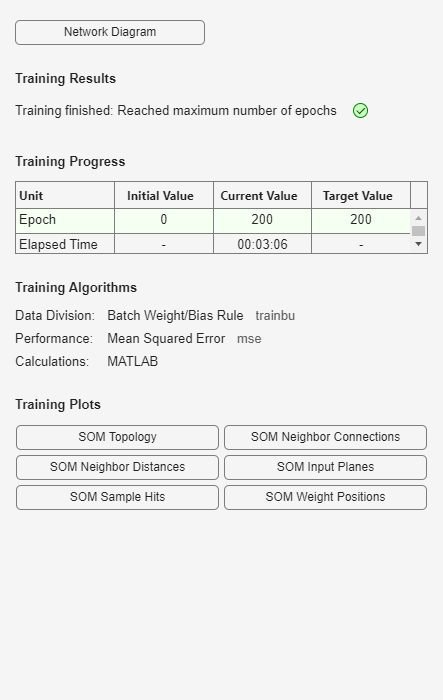

net = train(net, X');


%% 3) Asociar neuronas a clases
% Obtener índices de BMU para cada muestra de entrenamiento
bmu_indices = vec2ind(net(X'));  % Índices lineales (1..400)

% Asignar a cada neurona la clase mayoritaria entre sus BMUs
neuronClass = NaN(1, prod(dimension));
for i = 1:prod(dimension)
    idx = find(bmu_indices == i);
    if ~isempty(idx)
        labels = Y(idx);
        neuronClass(i) = mode(labels);
    end
end

%% 4) Cargar imágenes a clasificar
tmp = load('Test_numbers_HW1.mat');
Xtest_raw = tmp.Test_numbers.image;  % 784x10000

% Aplicar el mismo PCA
Xtest_centered = Xtest_raw' - mu;              % 10000 x 784
Xtest_pca = Xtest_centered * coeff(:,1:d_pca); % 10000 x 25

% Clasificar con SOM: encontrar BMU y asignar la clase
bmu_test = vec2ind(net(Xtest_pca'));  % Índices BMU para test
predicted_class = neuronClass(bmu_test);  % Clasificación por neurona

% Rellenar valores NaN con una clase por defecto (por ejemplo 0)
predicted_class(isnan(predicted_class)) = 0;
predicted_class = int32(predicted_class);  % Para guardar

%% 5) Guardar resultados en Group02_som.mat
name = ["Martin", "Diego", "David"];
PCA = d_pca;
class = predicted_class;  % Vector 1x10000 (int32)

save('Group02_som.mat', 'name', 'PCA', 'class');
fprintf('\nArchivo Group02_som.mat generado correctamente.\n');


Archivo Group02_som.mat generado correctamente.


**DLN**

% =========================================================================
% === SECCIÓN PARA LA RED NEURONAL CONVOLUCIONAL (DLN) ===
% =========================================================================
fprintf('\n--- Ejecutando Modelo DLN (CNN) ---\n');


--- Ejecutando Modelo DLN (CNN) ---


DLN: Iniciando el entrenamiento de la red con el 100% de los datos y Data Augmentation...


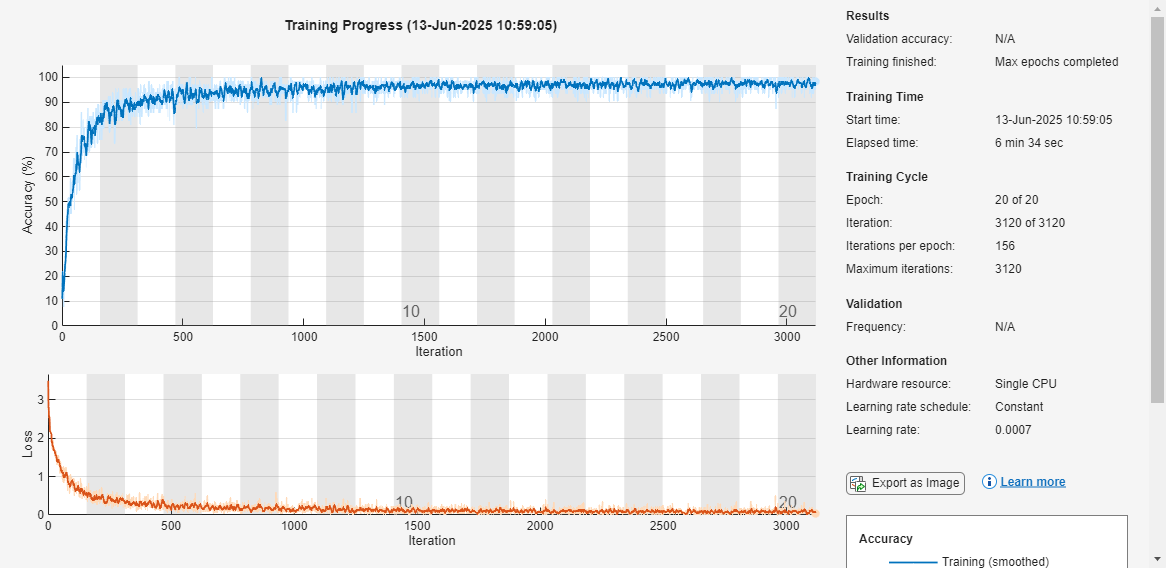

DLN: Entrenamiento completado en 417.34 segundos.


DLN: Guardando el modelo entrenado en trained_dln_model.mat...


DLN: Modelo guardado con éxito.


clc; clearvars -except name; close all;
rng(42);

%% 1) Cargar datos de entrenamiento
load('digits.mat');
X_train_raw = digits.image;
Y_train_raw = digits.label;
N_train = size(X_train_raw, 2);

%% 2) Preprocesamiento: Reconstruir imágenes 28x28 y normalizar a [0,1]
X_train = zeros(28,28,1,N_train,'single');
for i = 1:N_train
    img = reshape(X_train_raw(:,i), 28, 28)';
    X_train(:,:,1,i) = single(img) / 255;
end

%% 3) Etiquetas categóricas con 10 clases fijas para entrenamiento
Y_train = categorical(Y_train_raw, 0:9);

%% 4) Definición de la Arquitectura de la DLN y Hiperparámetros Óptimos
optimal_learningRate = 0.0007;
optimal_maxEpochs = 20;
fixed_miniBatchSize = 64;
fixed_numFiltersConv1 = 16;
fixed_numFiltersConv2 = 32;
fixed_numFiltersConv3 = 64;
fixed_fcLayerSize = 128;
fixed_dropoutRate = 0.5;
fixed_l2Regularization = 0.0001;

layers_dln = [
    imageInputLayer([28 28 1],'Name','input')
    convolution2dLayer(3,  fixed_numFiltersConv1,'Padding','same','Name','conv_1')
    batchNormalizationLayer(  'Name','bn_1')
    reluLayer(                'Name','relu_1')
    maxPooling2dLayer(2,'Stride',2,'Name','pool_1')
    convolution2dLayer(3, fixed_numFiltersConv2,'Padding','same','Name','conv_2')
    batchNormalizationLayer(  'Name','bn_2')
    reluLayer(                'Name','relu_2')
    maxPooling2dLayer(2,'Stride',2,'Name','pool_2')
    convolution2dLayer(3, fixed_numFiltersConv3,'Padding','same','Name','conv_3')
    batchNormalizationLayer(  'Name','bn_3')
    reluLayer(                'Name','relu_3')
    maxPooling2dLayer(2,'Stride',2,'Name','pool_3')
    fullyConnectedLayer(fixed_fcLayerSize,   'Name','fc_1')
    reluLayer(                 'Name','relu_4')
    dropoutLayer(fixed_dropoutRate,          'Name','dropout')
    fullyConnectedLayer(10,    'Name','fc_out')
    softmaxLayer(              'Name','softmax')
    classificationLayer(       'Name','classoutput')
];

%% 5) Entrenamiento de la DLN (o Carga de Modelo Pre-entrenado)
model_filename = 'trained_dln_model.mat'; % Nombre del archivo para guardar/cargar el modelo DLN

if exist(model_filename, 'file')
    fprintf('DLN: Cargando modelo pre-entrenado desde %s...\n', model_filename);
    load(model_filename, 'netDLN');
    fprintf('DLN: Modelo cargado con éxito.\n');
    trainingTime_dln = 0; % Tiempo de entrenamiento para esta ejecución es 0 si se cargó
else
    fprintf('DLN: Iniciando el entrenamiento de la red con el 100%% de los datos y Data Augmentation...\n');
    
    augTrain_dln = imageDataAugmenter( ...
        'RandRotation',[-10 10], ...
        'RandXTranslation',[-3 3], ...
        'RandYTranslation',[-3 3]);

    dsTrain_dln = augmentedImageDatastore([28 28], X_train, Y_train, ...
        'DataAugmentation', augTrain_dln);

    options_dln = trainingOptions('adam', ...
        'MaxEpochs',optimal_maxEpochs, ...
        'InitialLearnRate',optimal_learningRate, ...
        'MiniBatchSize',fixed_miniBatchSize, ...
        'Shuffle','every-epoch', ...
        'Verbose',false, ...
        'Plots','training-progress', ...
        'L2Regularization',fixed_l2Regularization);

    try
        tic;
        netDLN = trainNetwork(dsTrain_dln, layers_dln, options_dln);
        trainingTime_dln = toc;
        fprintf('DLN: Entrenamiento completado en %.2f segundos.\n', trainingTime_dln);
        close(findall(0, 'Type', 'figure', 'Tag', 'NNET_TRAININGPLOT'));
        
        % GUARDAR EL MODELO ENTRENADO para futuras ejecuciones
        fprintf('DLN: Guardando el modelo entrenado en %s...\n', model_filename);
        save(model_filename, 'netDLN');
        fprintf('DLN: Modelo guardado con éxito.\n');
    catch ME
        fprintf(2, 'DLN: Error durante el entrenamiento: %s\n', ME.message);
        netDLN = [];
    end
end


if isempty(netDLN)
    fprintf(2, 'DLN: No se pudo obtener el modelo DLN, saltando la clasificación de test.\n');
else
    %% 6) Cargar los datos de test del profesor
    % !!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
    % ADAPTAR ESTA LÍNEA: Cambiar 'Test_numbers_HW1.mat' por "Test_numbers.mat"
    % cuando el profesor proporcione el archivo.
    % !!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
    tmp = load('Test_numbers_HW1.mat'); % ASUMIR: variable 'image' dentro de 'Test_numbers'
    X_test_dln_raw = tmp.Test_numbers.image;

    N_test_dln = size(X_test_dln_raw, 2);

    %% 7) Preprocesamiento de los datos de test del profesor (sin Data Augmentation)
    X_test_dln = zeros(28,28,1,N_test_dln,'single');
    for i = 1:N_test_dln
        img = reshape(X_test_dln_raw(:,i), 28, 28)';
        X_test_dln(:,:,1,i) = single(img) / 255;
    end

    Y_dummy_test = categorical(zeros(1, N_test_dln), 0:9);
    dsTest_dln = augmentedImageDatastore([28 28], X_test_dln, Y_dummy_test);

    %% 8) Clasificación y Guardado de Resultados para DLN
    fprintf('DLN: Clasificando los datos de test del profesor...\n');
    tic;
    Y_pred_dln = classify(netDLN, dsTest_dln);
    classificationTime_dln = toc;

    % Convertir predicciones a array de enteros (0-9) 1x10000
    class = int32(double(string(Y_pred_dln))');

    % Variable "name" como cell array de char strings (máx 8 caracteres por nombre)
    name = {'Martin', 'Diego', 'David'}; 
    
    % Variable "PCA": 0 ya que no se usó PCA/Autoencoder explícito
    PCA = 0;

    % Guardar el archivo .mat con el nombre correcto y las variables requeridas
    save('Grupo02_dln.mat', 'name', 'PCA', 'class');

    fprintf('\nDLN: Archivo Grupo02_dln.mat generado correctamente.\n');
    fprintf('DLN: Tiempo de entrenamiento: %.2f segundos\n', trainingTime_dln);
    fprintf('DLN: Tiempo de clasificación en datos del profesor: %.4f segundos\n', classificationTime_dln);
end

DLN: Clasificando los datos de test del profesor...



DLN: Archivo Grupo02_dln.mat generado correctamente.


DLN: Tiempo de entrenamiento: 417.34 segundos


DLN: Tiempo de clasificación en datos del profesor: 3.2403 segundos
